## Envelope detection of AM signals (non-coherent demodulation)

AM signals can be demodulated with a coherent approach. This implies that the carrier must be regenerated at the receiver. In order to have the same phase and frequency at the transmitter and receiver, more complex methods are required. However, a simplified solution can be implemented with a non-coherent method. The resultant SNR in the demodulated signal will be lower in the non-coherent approach but the implemetation will not need of synchronization algorithms. In this hands-on activity, you will built a envelope detector for AM signals, instead of using analog circuits the processing will be perfomed on MATLAB.

**Equivalent signal processing for analog receiver.**

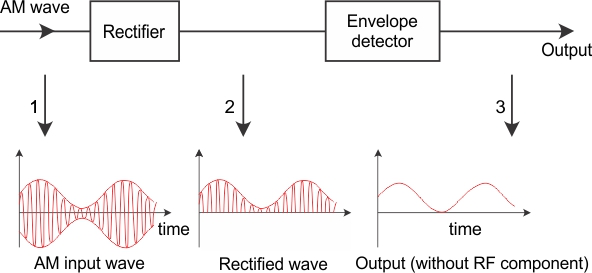

**Run GQRX and record a 5-second signal.**

The center frequency will assigned by the instructor. In the figure below the center frequency is 902.997 MHz. Note that the AM carrier frequency is greater than the center frequency. Tune the AM transmission until you hear an audio signal.

Record a 5-second signal.

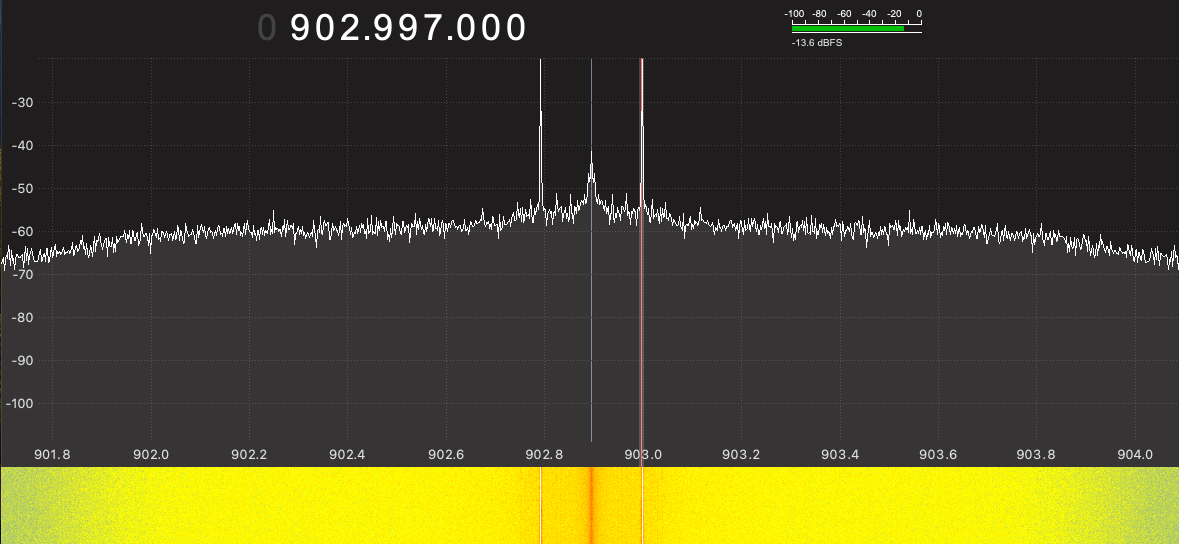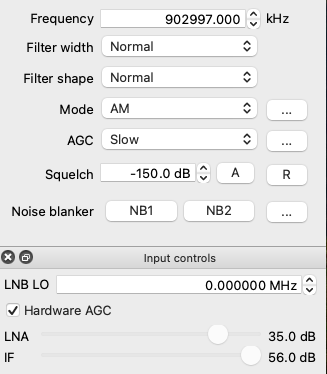

**Read the recording samples in MATLAB**

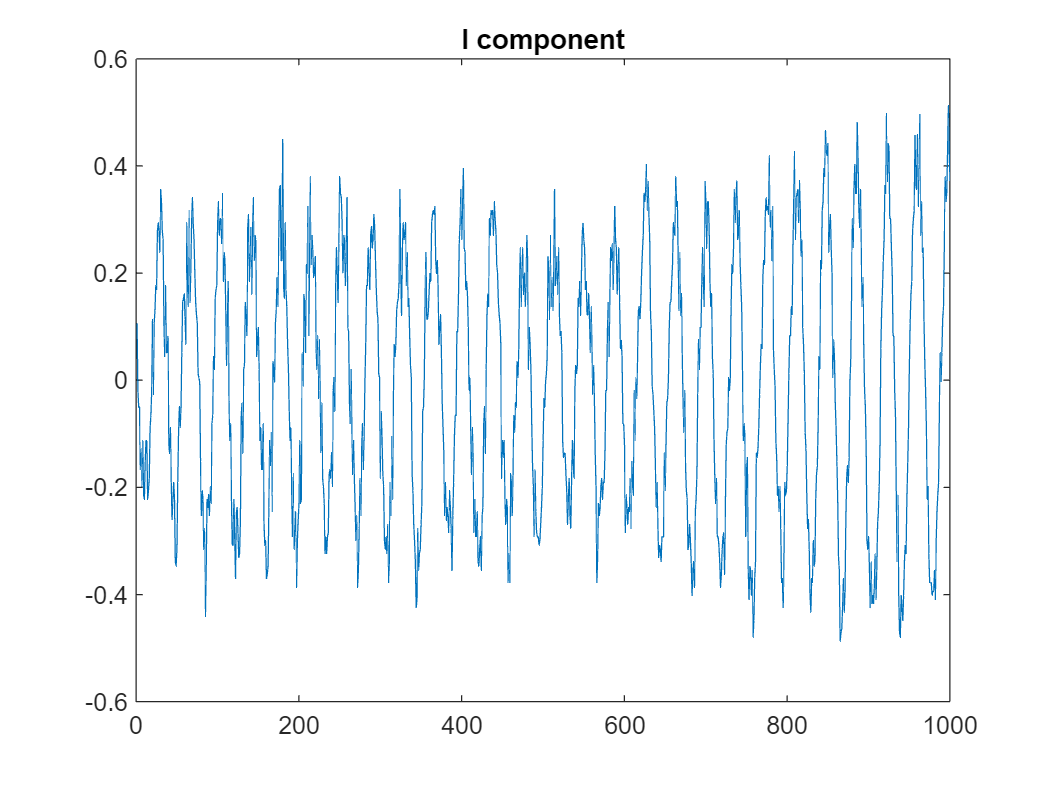

clear;
filename = 'gqrx_20231004_144751_903050000_1800000_fc.raw' ; 
fid = fopen(filename,'rb');
y = fread(fid,'float');
y = y(1:2:end) + 1i*y(2:2:end);
fclose(fid);
n_ = 1:length(y);
plot(real(y(1:1000)')) 
title('I component')

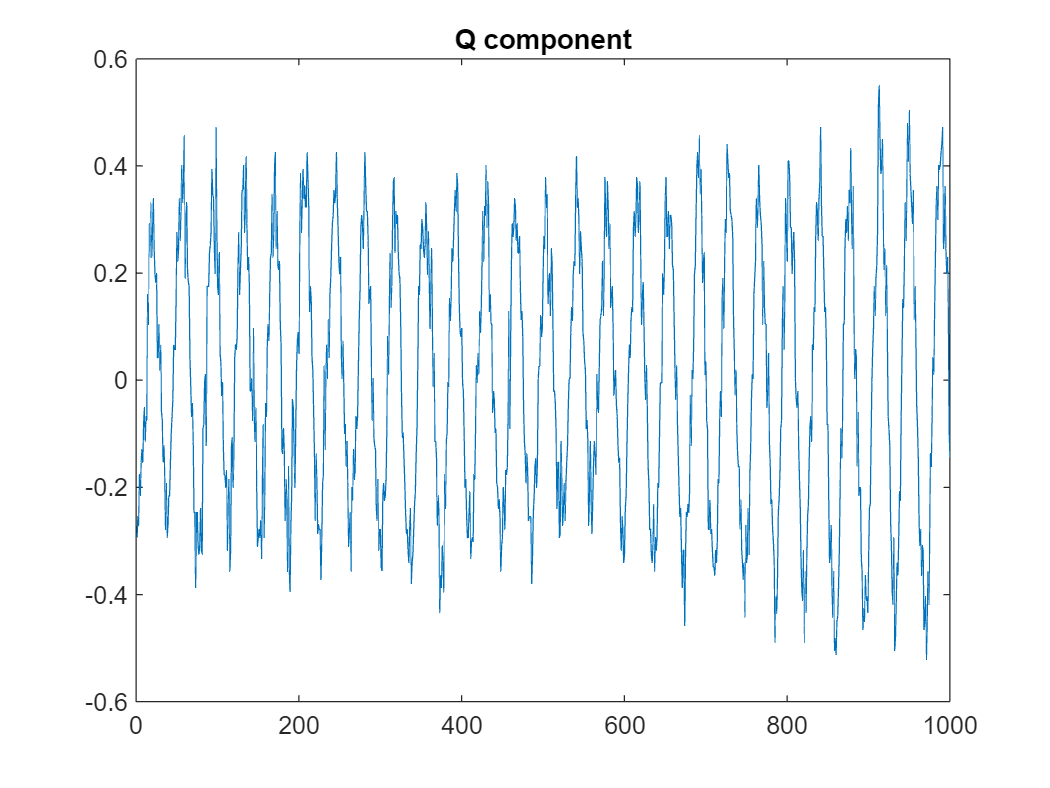

plot(imag(y(1:1000)')) 
title('Q component')

**Plot the spectrum and identify the frequency of the AM carrier**

 Find the carrier frequency from the spectrum. 

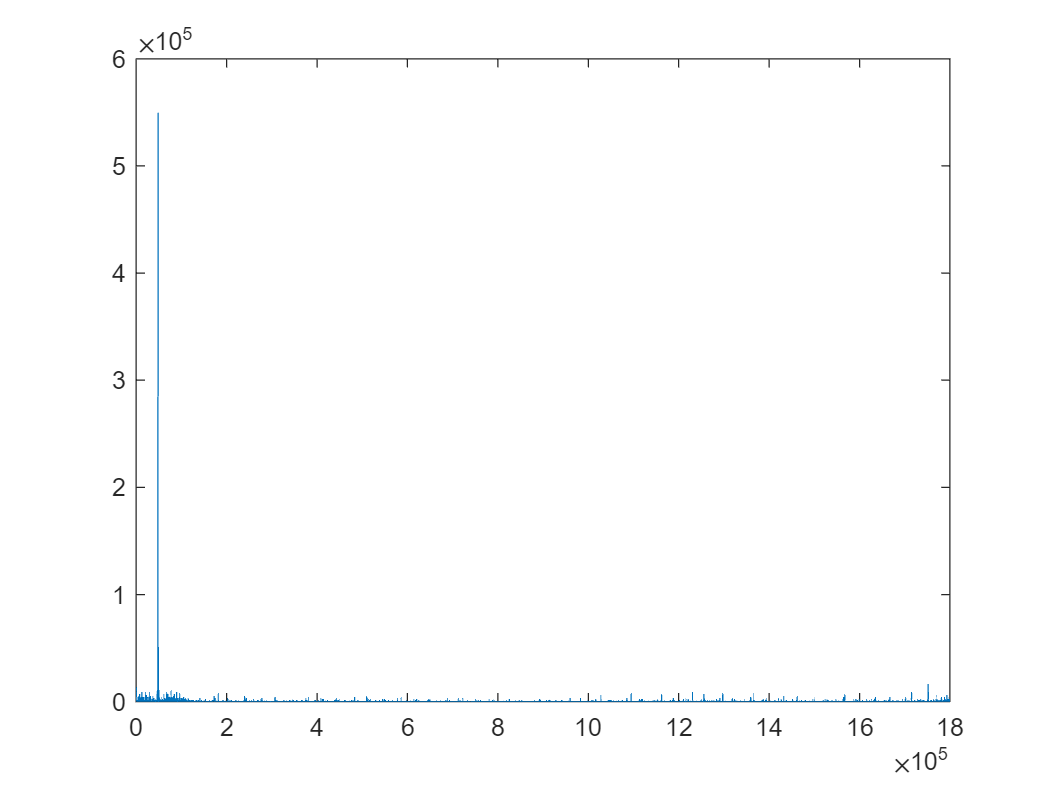

spectrum = fft(y(1:1800000));
plot(abs(spectrum))           % Find the carrier frequency from this plot

**Remove frequency components with a BPF.**

The signal contains components that are not associated with the message. Design a BPF to remove the unwanted frequency components, but first zoom in the previous plot and find the suitable cutoff frequencies for the BPF.

myfilter = bpf; %filter generated by filterDesigner

Unrecognized function or variable 'bpf'.

Numerator = myfilter.Numerator;
Denominator = 1;                           % <--- 1 for FIR Filters
am_rx = filter(Numerator, Denominator, y); 
plot(imag(am_rx(1:10000)))
title('AM signal')
spectrogram(am_rx, 500)

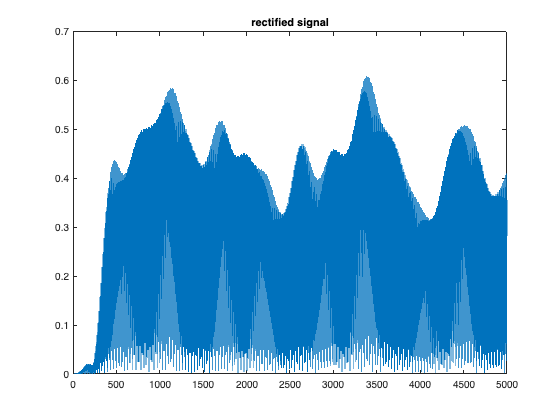

rect = abs(am_rx); % Equivalent to Signal rectification in a analog circuit
plot(rect(1:5000))
title('Rectified Signal')

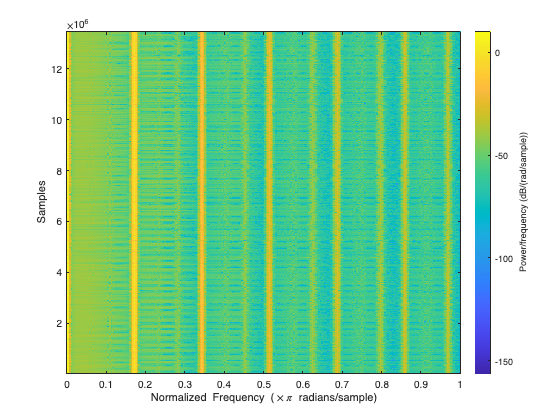

spectrogram(rect,500)

**Envelope detector.**

The envelope detector is a LPF, which removes high frequency components that do not belong to the message signal. Zoom in the above spectrogram and determine the cutoff frequency of the desired LPF. Design a LPF required for the following code.

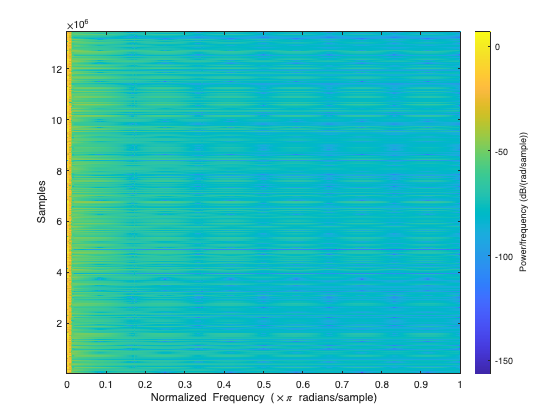

fir2 = lpf3; %  generated by filterDesigner
Numerator = fir2.Numerator;
Denominator = 1; 
message=filter(Numerator,Denominator,rect); 
message = message -mean(message); % remove DC constant
spectrogram(message,500)

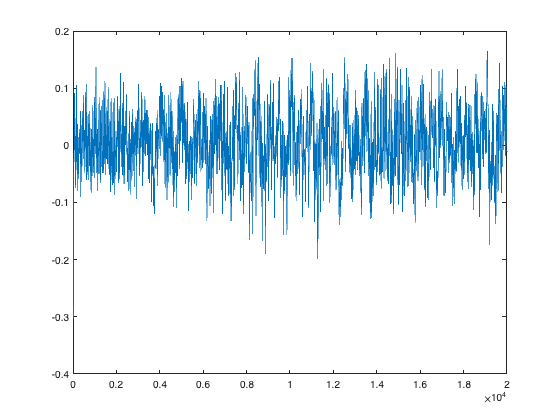

audio_m = message(1:24:end); % Downsampling, the new sample rate is 100 kSa per second
plot(audio_m(1:20000))


sound(audio_m,100000) 

Create a short video recording that captures the PC screen and the audio. You can use your smartphone for this. 